clc
clear all

1. Set the cfg.model_dir field to the path to the toolkit directory, and then add the "common" folder to your MATLAB path

% Add path to relevant functions
cfg.model_dir = '/Shared/boeslab/Users/jcgriffis/ibb_modeling_toolkit/model_code/';
addpath(fullfile(cfg.model_dir,'common'));
addpath(fullfile(cfg.model_dir, 'stacked_models'));

2. Specify the stacked model analysis parameters in a new cfg structure

% Set up cfg
cfg.parallel = 1; % Use parallel processing
cfg.model_spec = 'censemble'; % choose the meta model
cfg.method = 'Bag';
cfg.modality = 'other'; % non-lesion analysis
cfg.optimize_hyperparams = 1; % Optimize hyper-parameters
cfg.cross_validation = 1; % Do cross-validation
cfg.fit_explanatory_model = 0; % Don't fit an explaantory model

% Get default cfg for specified settings
cfg = get_default_stack_cfg(cfg);
cfg.cat_Y = 1;

% Modify defaults for relevant options
cfg.standardize = 0;
cfg.cost = [0, 2.3; 1, 0];

% Hyper-parameter optimization
cfg.hp_opt.cv_type = 'KFold'; % K-Fold CV
cfg.hp_opt.folds = 2; % Use 5-fold CV for hyperparameter optimization
cfg.hp_opt.repeats = 5; % 5 repeats of 5-fold CV 
cfg.hp_opt.opt_iter = 50; % Number of objective function evaluations
cfg.hp_opt.to_optimize(2).Range = [10, 50]; % Range for number of learners

% Permutation testing
cfg.cv.permutation = 0;
cfg.cv.n_perm = 20;

% Output directory
cfg.out_dir = '/Shared/boeslab/Users/jcgriffis/toolkit_paper_analyses/test/stacked_example2'

cfg = struct with fields:
                model_dir: '/Shared/boeslab/Users/jcgriffis/mlsm_code_repo/model_code/'
                 parallel: 1
               model_spec: 'censemble'
                   method: 'Bag'
                 modality: 'other'
     optimize_hyperparams: 1
         cross_validation: 1
    fit_explanatory_model: 0
                     cost: [2×2 double]
                    cat_Y: 1
                 learners: "tree"
                   hp_opt: [1×1 struct]
                confounds: 0
              standardize: 0
                strat_var: []
                       cv: [1×1 struct]
                  out_dir: '/Shared/boeslab/Users/jcgriffis/toolkit_paper_analyses/test/stacked_example2'


3. Specify the paths to the results files for the models that you want to stack as entries in a cell array

% Analysis parameters
cfg.model_paths = ["/Shared/boeslab/Users/jcgriffis/toolkit_paper_analyses/tutorial_results/pls_da_mae_token_lesion_d1_s0",...
    "/Shared/boeslab/Users/jcgriffis/toolkit_paper_analyses/tutorial_results/pls_da_mae_token_lesion_d0_s0",...
    "/Shared/boeslab/Users/jcgriffis/toolkit_paper_analyses/tutorial_results/pls_da_mae_token_discon_d0_s0",...    
"/Shared/boeslab/Users/jcgriffis/toolkit_paper_analyses/tutorial_results/pls_da_mae_token_flnm_d0_s0"]

cfg = struct with fields:
                model_dir: '/Shared/boeslab/Users/jcgriffis/mlsm_code_repo/model_code/'
                 parallel: 1
               model_spec: 'censemble'
                   method: 'Bag'
                 modality: 'other'
     optimize_hyperparams: 1
         cross_validation: 1
    fit_explanatory_model: 0
                     cost: [2×2 double]
                    cat_Y: 1
                 learners: "tree"
                   hp_opt: [1×1 struct]
                confounds: 0
              standardize: 0
                strat_var: []
                       cv: [1×1 struct]
                  out_dir: '/Shared/boeslab/Users/jcgriffis/toolkit_paper_analyses/test/stacked_example2'
              model_paths: ["/Shared/boeslab/Users/jcgriffis/toolkit_paper_analyses/tutorial_results/pls_da_mae_token_lesion_d1_s0"    "/Shared/boeslab/Users/jcgriffis/toolkit_paper_analyses/tutorial_results/pls_da_mae_token_lesion_d0_s0"    …    ]


Preallocating CV results
Outer CV repeats:1/5
Running KFold optimization for model hyperparameters
Number of folds: 2
Number of optimization iterations: 50
Repartitioning at each iteration


Running KFold optimization for model hyperparameters
Number of folds: 2
Number of optimization iterations: 50
Repartitioning at each iteration
Running KFold optimization for model hyperparameters
Number of folds: 2
Number of optimization iterations: 50
Repartitioning at each iteration
Running KFold optimization for model hyperparameters
Number of folds: 2
Number of optimization iterations: 50
Repartitioning at each iteration
Running KFold optimization for model hyperparameters
Number of folds: 2
Number of optimization iterations: 50
Repartitioning at each iteration
Outer CV repeats:2/5
Running KFold optimization for model hyperparameters
Number of folds: 2
Number of optimization iterations: 50
Repartitioning at each iteration
Running KFold optimization for model hyperparameters
Number of folds: 2
Number of optimization iterations: 50
Repartitioning at each iteration
Running KFold optimization for model hyperparameters
Number of folds: 2
Number of optimization iterations: 50
Repartition

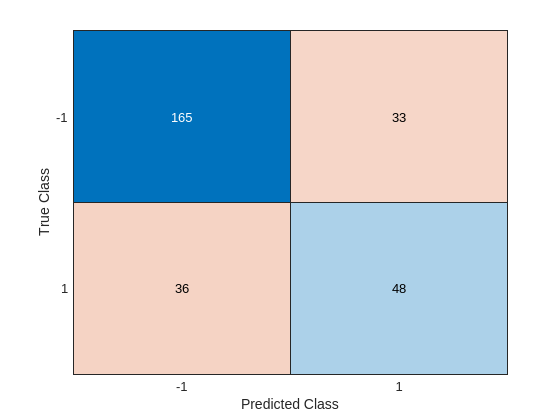

Full-sample Cross-Validation Fisher Exact Test: odds ratio=6.6667, p=4.2619e-11
Full-sample Cross-Validation Test Classification Accuracy (Group = -1): 0.83333
Full-sample Cross-Validation Test Classification Accuracy (Group = +1): 0.57143
Full-sample Cross-Validation Test Area Under ROC Curve: 0.81109


% Run stacking
[stacked_results, base_results] = run_model_stacking(cfg);

## Plot stacked results vs. base results

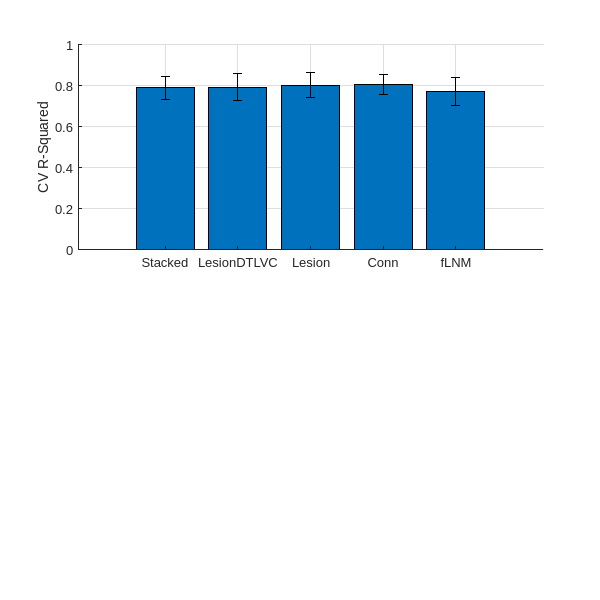

% Plot mean and SD model results
clf;
subplot(2,1,1)
bar(mean([stacked_results.roc_auc(:) base_results.roc_auc{1}(:) base_results.roc_auc{2}(:) base_results.roc_auc{3}(:) base_results.roc_auc{4}(:)],1));
hold on;
errorbar(mean([stacked_results.roc_auc(:) base_results.roc_auc{1}(:) base_results.roc_auc{2}(:) base_results.roc_auc{3}(:) base_results.roc_auc{4}(:)],1), std([stacked_results.roc_auc(:) base_results.roc_auc{1}(:) base_results.roc_auc{2}(:) base_results.roc_auc{3}(:) base_results.roc_auc{4}(:)],[],1), 'LineStyle', 'none', 'Color', 'k')
set(gca, 'XtickLabel', {'Stacked', 'LesionDTLVC', 'Lesion', 'Conn' 'fLNM'})
ylabel('CV R-Squared')
set(gcf, 'position', [0, 0, 600, 600]); box off; grid on;